clearvars
close all

## dataset

w0_theory = 0.5;
w1_theory = 1;

sigma = 0.05;

x1 = linspace(0,1,20)';
y_theory = w0_theory + w1_theory*x1;
y = y_theory + sigma*randn(length(x1),1);

%y = y_theory + 0.3*(rand(length(x1),1)-0.5);

## LS

M = length(y);
X = [ones(M,1) x1];
w_ls = pinv(X)*y;
y_hat = X*w_ls;

## Plot

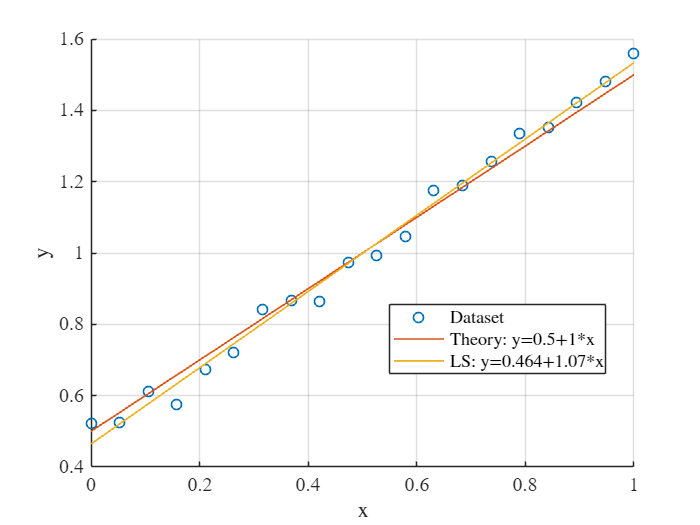

figure(1)
clf
hold on
plot(x1,y,'o',LineWidth=1)
plot(x1,y_theory,x1,y_hat,LineWidth=1)
hold off
grid on
legend('Dataset',['Theory: y=' num2str(w0_theory) '+' num2str(w1_theory) '*x'], ...
    ['LS: y=' num2str(w_ls(1),3) '+' num2str(w_ls(2),3) '*x'], ...
    Location='best',Interpreter='latex')
xlabel('x',Interpreter='latex')
ylabel('y',Interpreter='latex')
set(gca,'FontName','Times New Roman','FontSize',12)

## Projection matrix

P = X*pinv(X);
max(P-P',[],'all')

ans = 1.3878e-16

max(P-P*P,[],'all')

ans = 1.1102e-16

max(P*(eye(size(P))-P),[],"all")

ans = 9.3866e-17

## Properties of the error

e = y - y_hat;
max(e-(eye(size(P))-P)*y,[],"all")

ans = -4.1633e-17

X'*e

ans = 1.0e-14 *

    0.1554
    0.1443


y_hat'*e

ans = 2.2829e-15

mean(e)

ans = 7.7716e-17

## MSE

e'*e

ans = 0.0183

sum(y.^2) - w_ls(1)*y'*ones(M,1) - w_ls(2)*y'*x1

ans = 0.0183